# comparing phase extraction

## Hilbert

Instantaneous phase of theta-band activity was extracted by band-pass filtering the unsegmented data in a frequency band of 4.5–8.2 Hz (zero-shift Butterworth filter, 24 dB/octave) and applying the Hilbert transform. This was performed separately for each occipital electrode and then averaged (considering the circularity of phase)

filter design

d = designfilt('bandpassiir','FilterOrder',24, ...
    'HalfPowerFrequency1',4.5,'HalfPowerFrequency2',8, ...
    'SampleRate',srate*1000);
filt_trials = filtfilt(d,squeeze(norm_trials));


example for data filtering

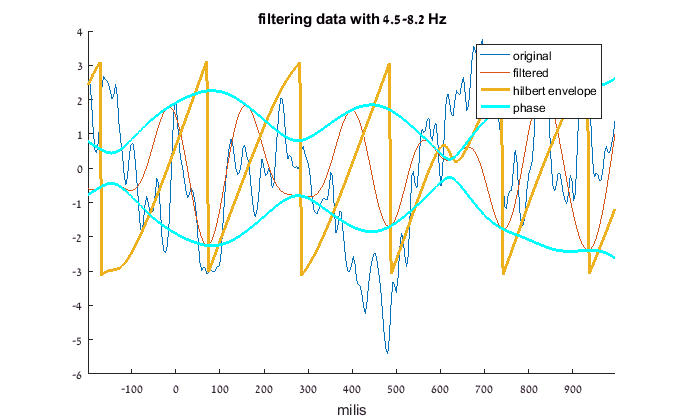

env = abs(hilbert(filt_trials(:,1)));
pha = angle(hilbert(filt_trials(:,1)));
figure;
hold on
plot(times,norm_trials(:,1,1))
plot(times,filt_trials(:,1))
plot(times,pha,'LineWidth',2)
plot(times,[-1;1]*env','c','LineWidth',2)
xlim([min(t) max(t)])
xlabel('milis')
legend({'original','filtered','phase','hilbert envelope'})
title('filtering data with 4.5-8.2 Hz')

applying filter to whole data results

phases_filtered = [];
for ind = 1:length(results)
    phases_filtered = [phases_filtered; angle(hilbert(filtfilt(d,squeeze(results{ind}.trials))))'];
end



## comparing filtered data ERPs

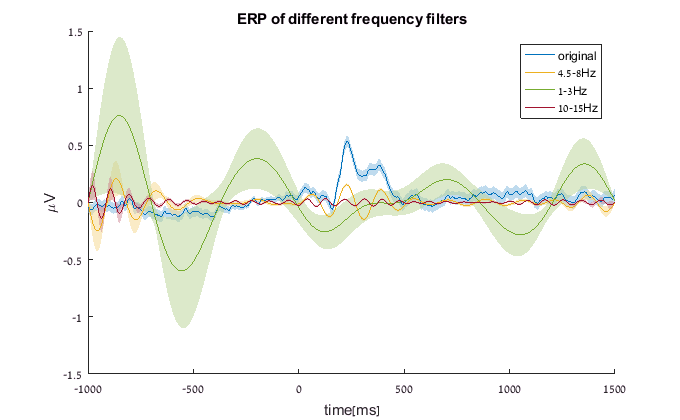

norm_filt_trials = filter_trials(norm_trials, 4.5, 8, srate);
figure;
hold on
varplot(times, squeeze(norm_trials))
varplot(times, squeeze(norm_filt_trials))
varplot(times, squeeze(filter_trials(norm_trials, 1, 3, srate)))
varplot(times, squeeze(filter_trials(norm_trials, 10, 15, srate)))
legend({'original', '4.5-8Hz','1-3Hz', '10-15Hz'})
xlabel time[ms]
ylabel '\muV'
title 'ERP of different frequency filters'

% xlim([min(t) max(t)])

draw the aligned plots:

and now with phases from hilbert transform

t_ind = find(times>150,1);
freq_inds = 8:13;

freq_norm  = mean(freqs(freq_inds));
% phase_shift = circ_mean(phases_filtered,[],1);
% phase_shift = round(phases_filtered./freq_norm./(2*pi)/SamplingInterval*1e6);
max_p3=zeros(size(times));
p2p_max=max_p3;
total_phase_shifts = get_hilbert_phase_shift(norm_trials, min_freq, max_freq, SamplingInterval);

figure;
varplot(times,abs(phase_shift)'/srate)
xlabel t[ms]
ylabel 'mean abs shift[ms]'
title 'mean abs shift (4.5-8.1 Hz)'

max_p3=zeros(size(times));
for ii = 1:length(times)
    mean_aligned = mean(align_trials_by_shift(norm_trials, total_phase_shifts(ii,:)),2);
    max_p3(ii) = max(mean_aligned(times>0 & times<500));
    p2p_max(ii) = max(mean_aligned(times>240 & times<450)) - min(mean_aligned(times>0 & times<450));
end
figure;
hold on
varplot(times,squeeze(norm_trials))
plot(times,max_p3)
legend({'grand ERP','max ERP'})
xlabel t[ms]
ylabel '\muV'
title 'max ERP'
figure;
varplot(times,squeeze(norm_trials))
hold on
for ii = -400:400:800    
    varplot(times,align_trials_by_shift(norm_trials, total_phase_shifts(find(times>ii,1),:))); 
end
legend(['orignal', string(-400:400:800)])
ylabel '\muV'
title 'ERP for for align on different time points'


## compare filt before and after ERP

filt_erp = filtfilt(d,total_erps);
mean_filt_trials = [];
for subj_ind = 1:length(results)
    subj_filt_trials = filtfilt(d,squeeze(results{subj_ind}.trials));
    for cond_ind = 1:size(theta_power_condition,2)
        mean_filt_trials(:,cond_ind,subj_ind) = mean(subj_filt_trials(:, results{subj_ind}.condition_positions == cond_ind),2);
    end
end
max(abs(filt_erp(:)-mean_filt_trials(:)))

function filt_trials = filter_trials(trials, freq_min, freq_max, srate)
d = designfilt('bandpassiir','FilterOrder',24, ...
                'HalfPowerFrequency1',freq_min,'HalfPowerFrequency2',freq_max, ...
                'SampleRate',srate*1000);
filt_trials = filtfilt(d,squeeze(trials));
end
